**Econ 612 Assignment 1 - Empirical**

**Nond Pruesiri**

**Problem 1 **

1(a)  I use the 70-day time series of exchange rate (Thai Baht per Unitied States Dollar). It is a relatively stable time series with a narrow range of value, and thus, I do not take log-difference of the series.

1(b) Load the data into MATLAB

thbusd = readtable('usdthb.xls','range','B2:B72');

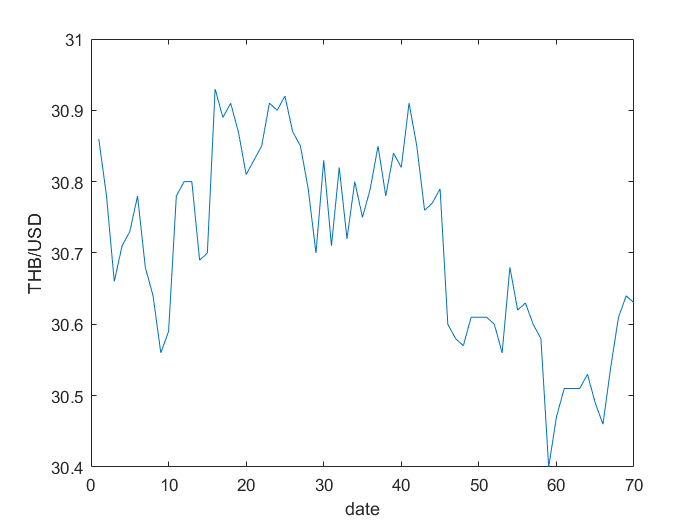

thbusd = table2array(thbusd);
plot(thbusd);
xlabel('date')         %label X-axis
ylabel('THB/USD')      %label Y-axis

1(C) Create a function that provides summary statistics

********sumstats function**********

%function[stats]=sumstats(y)
%    meany = mean(y);
%    mediany = median(y);
%    maxy = max(y);
%    miny = min(y);
%    sdy = std(y);
%    k = kurtosis(y);
%    [jbstat,p] = jbtest(y);
%    label = ["mean" "median" "maximum" 'minimum' "standard deviation" "kurtosis" 
%                "Jarque-Bera Statistics" "Jarque-Bera P-Value"];
%    value = [meany mediany maxy miny sdy k, jbstat,p];
%    stats = vertcat(label,value)
%end

Display sumary statistics

summary = transpose(sumstats(thbusd))

summary = 8×2 string array
    "mean"                      "30.7104"  
    "median"                    "30.715"   
    "maximum"                   "30.93"    
    "minimum"                   "30.4"     
    "standard deviation"        "0.134858" 
    "kurtosis"                  "2.00452"  
    "Jarque-Bera Statistics"    "0"        
    "Jarque-Bera P-Value"       "0.0967981"
